syms x y [2 1] real
x % x1 x2

$$x = \left(\begin{array}{c} x_{1}\\ x_{2} \end{array}\right)$$

y % y1 y2

$$y = \left(\begin{array}{c} y_{1}\\ y_{2} \end{array}\right)$$

A=[2 2; 1 1];
x=sym('x',[2 1],'real');
y=sym('y',[2 1],'real');
expand(x'*A*y)

$$ans = 2\,x_{1}\,y_{1}+2\,x_{1}\,y_{2}+x_{2}\,y_{1}+x_{2}\,y_{2}$$

Verify each property of the dot product to see if the above expression is a dot product

A=[2 2; 1 1];
syms x y z [2 1] real;
syms a b real;
F=@(x,y) x'*A*y

F = function_handle with value:
    @(x,y)x'*A*y


Bilinear Property:

%expand(F(a*x+b*y,z) - a*F(x,z)+b*F(y,z) ) )
expand( (F(a*x+b*y,z)) - (a*F(x,z)+b*F(y,z)) )

$$ans = 0$$

Symmetry property:

expand((F(x,y)) - (F(y,x))) % 

$$ans = x_{1}\,y_{2}-x_{2}\,y_{1}$$

% it does not hold the symmetric property, then isn't a dot product

Positive definitivess property:

S=simplify(F(x,x),50)

$$S = \left(x_{1}+x_{2}\right)\,\left(2\,x_{1}+x_{2}\right)$$

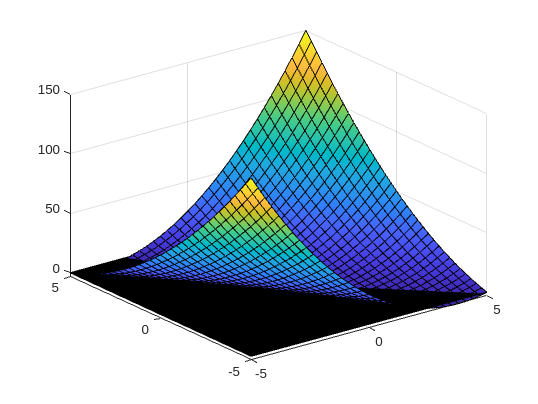

fsurf(S); hold on; AX=axis;
surf([AX(1:2);AX(1:2)],[AX(3:4);AX(3:4)]',zeros(2,2),'FaceColor','black');

X2=solve(S,x2)

$$X2 = \left(\begin{array}{c} -x_{1}\\ -2\,x_{1} \end{array}\right)$$

disp(factor(S))

$$\left(\begin{array}{cc} x_{1}+x_{2} & 2\,x_{1}+x_{2} \end{array}\right)$$

As=sym([2 2; 1 1]);
NA=null(As)

$$NA = \left(\begin{array}{c} -1\\ 1 \end{array}\right)$$

NAT=null(As')

$$NAT = \left(\begin{array}{c} -\frac{1}{2}\\ 1 \end{array}\right)$$

disp(eig(A))

     3
     0



Now verify that $\langle x,y\rangle = 2x_1y_1 + x_1y_2+x_2y_1-x_2y_2$ is a dot product

clf;
syms x y [2 1] real;
A=sym([2 1; 1 -1]);
F=@(x,y) x'*A*y

F = function_handle with value:
    @(x,y)x'*A*y


expand( (F(a*x+b*y,z)) - (a*F(x,z)+b*F(y,z)) ) % Bilinear property Holds

$$ans = 0$$

expand((F(x,y)) - (F(y,x))) % Symmetry Holds

$$ans = 0$$

%Since it is a symmetricl matrix we can verify positive definitness with
%eignvalues
A=([2 1; 1 -1]);
(disp(eig(A))); % First term is negative, so positive defintness doesn't hold, 

   -1.3028
    2.3028



% Then is not a dot product
S=simplify(F(x,x),50)

$$S = 2\,{x_{1}}^{2}+2\,x_{1}\,x_{2}-{x_{2}}^{2}$$

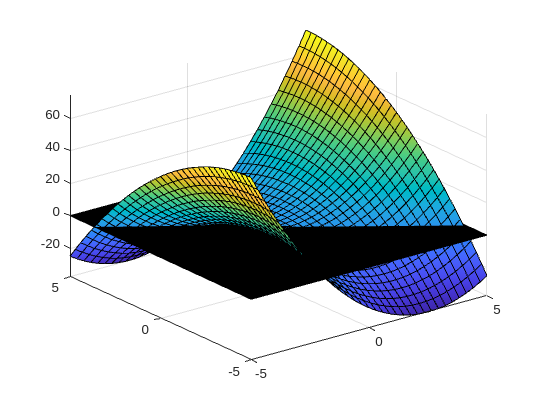

fsurf(S); hold on; AX=axis;
surf([AX(1:2);AX(1:2)],[AX(3:4);AX(3:4)]',zeros(2,2),'FaceColor','black');

X2=solve(S,x2)

$$X2 = \left(\begin{array}{c} x_{1}+\sqrt{3}\,x_{1}\\ x_{1}-\sqrt{3}\,x_{1} \end{array}\right)$$

Now verify that $\langle x,y\rangle = x_1y_1+5x_2y_2+12x_3y_3-2x_1y_2-2x_2y_1+3x_1y_3+3x_3y_1-7x_2y_3-7x_3y_2$ is a dot product

syms x y z [3 1] real;
syms a b real;
f=x1*y1 + 5*x2*y2 + 12*x3*y3 - 2*x1*y2 - 2*x2*y1 + 3*x1*y3 + 3*x3*y1 - 7*x2*y3 - 7*x3*y2

$$f = x_{1}\,y_{1}-2\,x_{1}\,y_{2}-2\,x_{2}\,y_{1}+3\,x_{1}\,y_{3}+5\,x_{2}\,y_{2}+3\,x_{3}\,y_{1}-7\,x_{2}\,y_{3}-7\,x_{3}\,y_{2}+12\,x_{3}\,y_{3}$$

[c,t]=coeffs(f) % Get coeffs from function

$$c = \left(\begin{array}{ccccccccc} 1 & -2 & 3 & -2 & 3 & 5 & -7 & -7 & 12 \end{array}\right)$$

$$t = \left(\begin{array}{ccccccccc} x_{1}\,y_{1} & x_{1}\,y_{2} & x_{1}\,y_{3} & x_{2}\,y_{1} & x_{3}\,y_{1} & x_{2}\,y_{2} & x_{3}\,y_{2} & x_{2}\,y_{3} & x_{3}\,y_{3} \end{array}\right)$$

n = 3

$$A = \left(\begin{array}{ccc} 1 & -2 & -7\\ -2 & 3 & -7\\ 3 & 5 & 12 \end{array}\right)$$

A=[1 -2 3; -2 5 -7;3 -7 12]

A =      1    -2     3
    -2     5    -7
     3    -7    12


F=@(x,y) x'*A*y;

simplify(expand( F(a*x+b*y,z) == a*F(x,z)+b*F(y,z) ))% Check bilinearity

$$ans = \mathrm{symtrue}$$

simplify(F(x,y)-F(y,x))

$$ans = 0$$

all(eig(A) > 0)

ans = logical
   1
